Xdim = 1;
Ydim = 1;
Zdim = 1;
XNdim = 100;
YNdim = 100;
ZNdim = 100;
Tdim = 100;
c = 1;
G = 1;

Xl = linspace(-XNdim*Xdim,XNdim*Xdim,2*XNdim+1);
Yl = linspace(-YNdim*Ydim,YNdim*Ydim,2*YNdim+1);
Zl = linspace(-ZNdim*Zdim,ZNdim*Zdim,2*ZNdim+1);

[X,Y,Z] = meshgrid(Xl,Yl,Zl);

XNdim = numel(Xl);
YNdim = numel(Yl);
ZNdim = numel(Zl);

h00 = zeros(XNdim,YNdim,ZNdim);
h0j = zeros(XNdim,YNdim,ZNdim,3);
hij = zeros(XNdim,YNdim,ZNdim,3,3);
h00l = zeros(XNdim,YNdim,ZNdim);
h0jl = zeros(XNdim,YNdim,ZNdim,3);
hijl = zeros(XNdim,YNdim,ZNdim,3,3);
p   = zeros(XNdim,YNdim,ZNdim);
rho = zeros(XNdim,YNdim,ZNdim);
vj  = zeros(XNdim,YNdim,ZNdim,3);

deltaij = zeros(1,1,1,3,3);

deltaij(1,1,1,1,1) = 1;
deltaij(1,1,1,2,2) = 1;
deltaij(1,1,1,3,3) = 1;


rho1 = 1;
R1   = 10;
r1   = [0,0,0];
v1   = [0,0,0];
rho2 = .5;
R2   = 5;
r2   = [0,40,0];
v2   = [.5,0,0];

rho1m = ((X-r1(1)).^2+(Y-r1(2)).^2+(Z-r1(3)).^2)<R1.^2;
rho2m = ((X-r2(1)).^2+(Y-r2(2)).^2+(Z-r2(3)).^2)<R2.^2;

rho  = rho1m*rho1+rho2m*rho2;

rho = imgaussfilt3(rho,1.);
p = rho*c^2;

vj(:,:,:,1) = v1(1) * rho1m+v2(1) * rho2m; % x-component
vj(:,:,:,2) = v1(2) * rho1m+v2(2) * rho2m; % y-component
vj(:,:,:,3) = v1(3) * rho1m+v2(3) * rho2m; % z-component



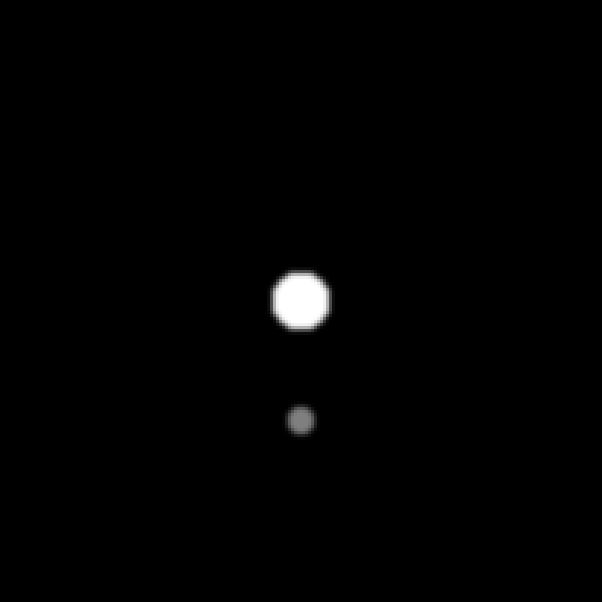

I = imshow(squeeze(rho(:,:,ZNdim/2+.5)),[0 1],InitialMagnification=300);
hold on

drawnow;

eps = .0001;
dt = .01;

for i = 1:Tdim

h00 = dt^2*16*pi*G.*(rho)+dt^2*c^2*6*del2(h00)+2*h00-h00l;
h0j = dt^2*16*pi*G.*(rho+p/c^2)+dt^2*c^2*6*del2(h0j)+2*h0j-h0jl;
hij = dt^2*16*pi*G.*(rho)+dt^2*c^2*6*del2(hij)+2*hij-hijl;

rho = rho - dt*divergence(X,Y,Z,(rho+p/c^2).*vj(:,:,:,1),(rho+p/c^2).*vj(:,:,:,2),(rho+p/c^2).*vj(:,:,:,3));
[p1t,p2t,p3t] = gradient(p,Xl,Yl,Zl);
[hb1t,hb2t,hb3t] = gradient(h00+sum(h0j,4),Xl,Yl,Zl);
vj = vj - dt.*cat(4,p1t,p2t,p3t)./(rho+p/c^2+eps)-dt.*cat(4,hb1t,hb2t,hb3t);

p = rho*c^2;

set(I,'CData',squeeze(rho(:,:,ZNdim/2+.5)));
drawnow;
end